# 5.4 FIR 滤波器的结构：直接型（横截型）、级联型、线性相位型；四类线性相位 h(n)

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：直接型（横截型）——教材例 5.5：h(n)=0.9^n，0≤n≤10；一条延时链、N 个乘法器、累加

h5 = 0.9.^(0:10); Nh = 30; delta = [1 zeros(1, Nh-1)]; u = ones(1, Nh);
y1 = transversal(h5, delta); s1 = transversal(h5, u);
errT = max(abs([y1 - filter(h5, 1, delta), s1 - filter(h5, 1, u)]));

## 演示2：级联型——教材例 5.6：H(z)=(1+1.72z^-1+0.81z^-2)(1+1.17z^-1+0.85z^-2)

c1 = [1 1.72 0.81]; c2 = [1 1.17 0.85]; hC = conv(c1, c2);   % 乘开就是直接型的 h(n)
yCas = filter(c2, 1, filter(c1, 1, delta)); errC = max(abs(yCas - filter(hC, 1, delta)));
zC = [roots(c1); roots(c2)];                                  % 两节的零点都是共轭对

## 演示3：线性相位型——h(n)=h(N−1−n) 时先把对称的两个样本相加再乘系数，乘法器减半（教材式 (5.3.4)、图 5.3.6）

hL = [1 2 3 4 4 3 2 1]/20; N = numel(hL);
x = randn(1, 200); yLin = linear_phase_sym(hL, x); errL = max(abs(yLin - filter(hL, 1, x)));
w = linspace(0, pi, 1024); HLw = dtft_resp(hL, 1, w); ph = unwrap(angle(HLw));
idx = w < 0.3*pi; pfit = polyfit(w(idx), ph(idx), 1); slope = pfit(1);   % 相位斜率应为 −(N−1)/2 = −3.5
multsDirect = N; multsLinear = ceil(N/2);

## 演示4：四类线性相位 FIR（对称/反对称 × N 奇/偶）：H(e^j0)、H(e^jπ) 的必然零点

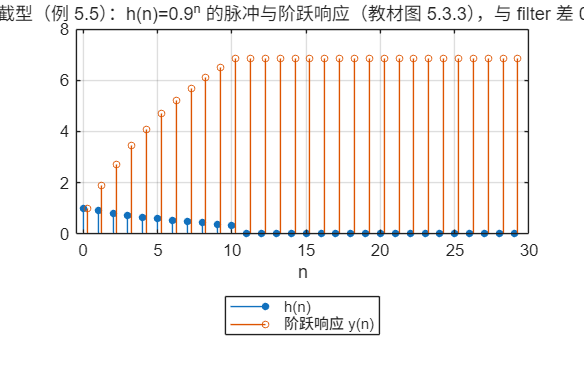

hI   = [1 2 3 2 1]/9;          % I 型：对称，N 奇
hII  = [1 2 3 3 2 1]/12;       % II 型：对称，N 偶 → H(e^{jπ})=0
hIII = [1 2 0 -2 -1]/6;        % III 型：反对称，N 奇（中点必为 0）→ H(e^{j0})=H(e^{jπ})=0
hIV  = [1 2 3 -3 -2 -1]/12;    % IV 型：反对称，N 偶 → H(e^{j0})=0
types = {hI, hII, hIII, hIV}; names = {'I 型：对称，N=5', 'II 型：对称，N=6', 'III 型：反对称，N=5', 'IV 型：反对称，N=6'};
H0 = zeros(1, 4); Hpi = zeros(1, 4);
for i = 1:4, hh = types{i}; H0(i) = abs(sum(hh)); Hpi(i) = abs(sum(hh .* (-1).^(0:numel(hh)-1))); end

if ~LIVE, f1 = figure('Name','04 FIR 结构','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(0:Nh-1, y1, 'filled', 'MarkerSize', 4); hold on; stem((0:Nh-1)+0.25, s1, 'MarkerSize', 4);
grid on; xlim([-0.5 Nh]); xlabel('n');
title(sprintf('① 横截型（例 5.5）：h(n)=0.9^n 的脉冲与阶跃响应（教材图 5.3.3），与 filter 差 %.1e', errT));
legend('h(n)', '阶跃响应 y(n)');

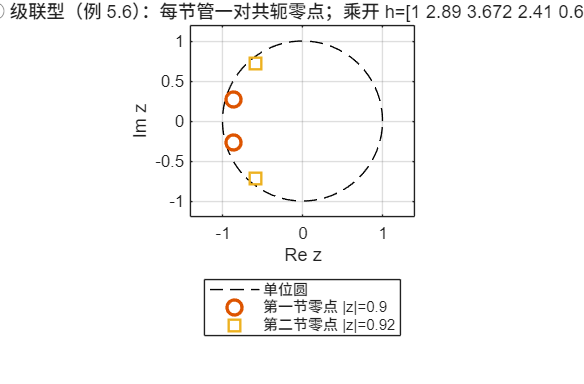

newpanel(); tt = linspace(0, 2*pi, 400); plot(cos(tt), sin(tt), 'k--'); hold on; axis equal; grid on;
plot(real(zC(1:2)), imag(zC(1:2)), 'o', 'MarkerSize', 9, 'LineWidth', 2); plot(real(zC(3:4)), imag(zC(3:4)), 's', 'MarkerSize', 9, 'LineWidth', 2);
xlim([-1.4 1.4]); ylim([-1.2 1.2]); xlabel('Re z'); ylabel('Im z');
title(sprintf('② 级联型（例 5.6）：每节管一对共轭零点；乘开 h=[%s]', strjoin(compose('%.4g', hC), ' ')));
legend('单位圆', '第一节零点 |z|=0.9', '第二节零点 |z|=0.92');

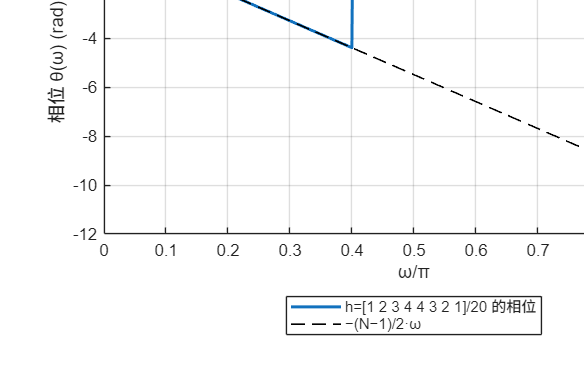

newpanel(); plot(w/pi, ph, 'LineWidth', 1.8); hold on; plot(w/pi, -(N-1)/2*w, 'k--', 'LineWidth', 1);
grid on; xlabel('ω/π'); ylabel('相位 θ(ω) (rad)');
title(sprintf('③ 线性相位型：乘法器 %d→%d，与直接型差 %.1e；相位斜率 %.2f = −(N−1)/2', multsDirect, multsLinear, errL, slope));
legend('h=[1 2 3 4 4 3 2 1]/20 的相位', '−(N−1)/2·ω');

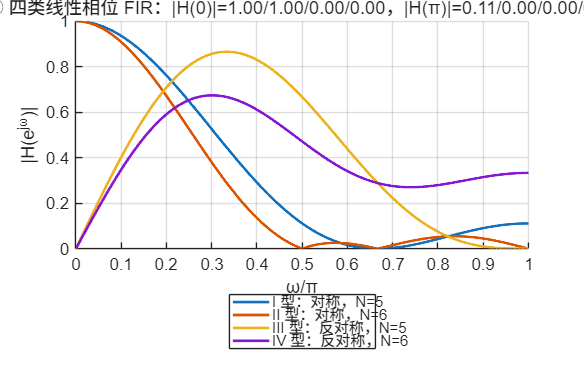

newpanel(); hold on;
for i = 1:4, plot(w/pi, abs(dtft_resp(types{i}, 1, w)), 'LineWidth', 1.6); end
grid on; xlabel('ω/π'); ylabel('|H(e^{jω})|');
title(sprintf('④ 四类线性相位 FIR：|H(0)|=%.2f/%.2f/%.2f/%.2f，|H(π)|=%.2f/%.2f/%.2f/%.2f', H0, Hpi));
legend(names);

if ~LIVE, sgtitle('FIR 结构：横截型最直接；级联型按零点分组；对称 h(n) 让乘法器减半，代价是相位必然线性——这正是想要的'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '04-fir-structures.png'), 'Resolution', 150); end

## 教师核验

assert(errT < 1e-12 && errC < 1e-12 && errL < 1e-12, '三种 FIR 结构应与 filter 逐点一致');
assert(abs(slope + (N-1)/2) < 1e-6, '相位斜率应为 −(N−1)/2');
assert(Hpi(2) < 1e-12 && H0(3) < 1e-12 && Hpi(3) < 1e-12 && H0(4) < 1e-12 && H0(1) > 0.5 && Hpi(1) > 0.05, '四类的固有零点不符');
assert(all(abs(abs(zC) - [0.9; 0.9; sqrt(0.85); sqrt(0.85)]) < 1e-12), '例 5.6 零点模不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'err_transversal', errT, 'h_cascade_expanded', hC, 'err_cascade', errC, 'cascade_zero_radius', abs(zC).', ...
    'err_linear_phase', errL, 'phase_slope', slope, 'mults_direct', multsDirect, 'mults_linear', multsLinear, ...
    'H0_types_I_to_IV', H0, 'Hpi_types_I_to_IV', Hpi, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-fir-structures.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

         matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                 run_at: '2026-09-18 20:50:15'
        err_transversal: 0
     h_cascade_expanded: [1 2.8900 3.6724 2.4097 0.6885]
            err_cascade: 0
    cascade_zero_radius: [0.9000 0.9000 0.9220 0.9220]
       err_linear_phase: 2.2204e-16
            phase_slope: -3.5000
           mults_direct: 8
           mults_linear: 4
       H0_types_I_to_IV: [1 1 2.7756e-17 1.3878e-17]
      Hpi_types_I_to_IV: [0.1111 1.3878e-17 0 0.3333]
      all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results


## 本地函数

function y = transversal(h, x)
% 横截型：一条延时链 xd(k)=x(n−k)，N 个乘法器，一个累加
Nt = numel(h); xd = zeros(1, Nt-1); y = zeros(size(x));
for n = 1:numel(x)
    y(n) = h(1)*x(n) + sum(h(2:end).*xd);
    xd = [x(n) xd(1:end-1)];
end
end

function y = linear_phase_sym(h, x)
% 线性相位型（h 对称）：y(n)=Σ_{k=0}^{N/2−1} h(k)[x(n−k)+x(n−(N−1−k))]（N 奇时再加中间一项）
Nt = numel(h); L = floor(Nt/2); xd = zeros(1, Nt-1); y = zeros(size(x));
for n = 1:numel(x)
    xs = [x(n) xd];                                   % xs(k+1)=x(n−k)，k=0..N−1
    acc = 0;
    for k = 0:L-1, acc = acc + h(k+1)*(xs(k+1) + xs(Nt-k)); end
    if mod(Nt, 2) == 1, acc = acc + h(L+1)*xs(L+1); end
    y(n) = acc; xd = xs(1:end-1);
end
end

function H = dtft_resp(b, a, w)
z = exp(-1i*w(:).');
H = polyval(fliplr(b), z) ./ polyval(fliplr(a), z);
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end